[x, Fs] = audioread("audio_chunk_1000.wav");
sound(x, Fs);

N = length(x);
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);

X = fft(x);

CONVOLUTION FILTER: 

xSmooth = conv2(x,0.8, "same")

xSmooth =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


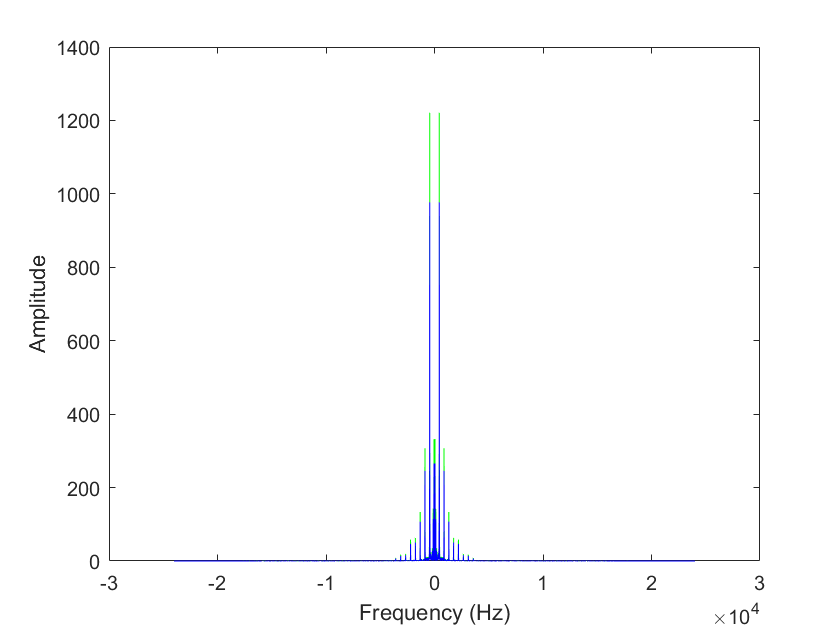

sound(xSmooth, Fs);
XSmooth = fft(xSmooth);

%frequency vs. amplitude of filtered and unfiltered
plot(f,fftshift(abs(X)),'g',f,fftshift(abs(XSmooth)),'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude')

BAND PASS FILTER: 

xBand = bandpass(x,[.01, .999])

xHigh = 	1.0e+50 *

    3.4799    3.4799
    3.2824    3.2824
    3.0821    3.0821
    2.8793    2.8793
    2.6741    2.6741
    2.4668    2.4668
    2.2575    2.2575
    2.0464    2.0464
    1.8337    1.8337
    1.6197    1.6197


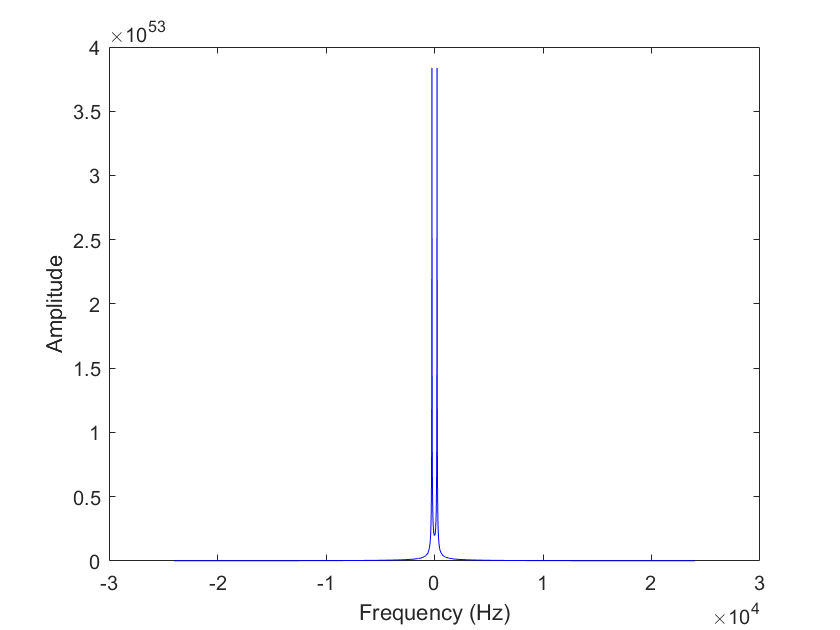

sound(xBand, Fs);
XBand = fft(xBand);

%frequency vs. amplitude of filtered and unfiltered
plot(f,fftshift(abs(XBand)),'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude')

audiowrite("bandpass.wav",xBand,Fs);
audiowrite("convolution.wav",xSmooth,Fs);
